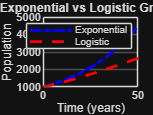

% population_growth_clean.m
% This script simulates and compares exponential and logistic population growth models
% using fixed parameters and visualizes the results in a single plot.

%% Define Simulation Parameters
% Initial population size
P0 = 1000;

% Growth rate (per year)
r = 0.03;

% Carrying capacity for the logistic model
K = 5000;

% Time span for the simulation (in years)
t = 0:1:50;

%% Calculate Exponential Growth
% The exponential model assumes unlimited resources.
% Formula: P(t) = P0 * exp(r * t)
P_exp = P0 * exp(r * t);

%% Calculate Logistic Growth
% The logistic model includes a carrying capacity, limiting growth.
% Formula: P(t) = K / (1 + ((K - P0)/P0) * exp(-r * t))
P_log = K ./ (1 + ((K - P0)/P0) * exp(-r * t));

%% Plot the Results
% Create a figure to display both models
figure

% Plot exponential growth in blue dash-dot line
plot(t, P_exp, 'b-.', 'LineWidth', 2)
hold on

% Plot logistic growth in red dashed line
plot(t, P_log, 'r--', 'LineWidth', 2)

% Label the axes
xlabel('Time (years)')
ylabel('Population')

% Add a title to the plot
title('Exponential vs Logistic Growth')

% Add a legend to distinguish the models
legend('Exponential', 'Logistic')

% Add grid lines for better readability
grid on


%% Summary
% This simulation demonstrates how exponential growth leads to unlimited increase,
% while logistic growth levels off due to resource limitations.
% The plot visually compares both models over a 50-year period.
